# ICE 6: Pole Placement

A = [-6 -11 -6; 1 0 0; 0 1 0];
B = [1; 0; 0];
C = [0 1 1.5];

ORSys = ss(A, B, C, 0);
ORTF = tf(ORSys)

ORTF =
 
         s + 1.5
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


poles = pole(ORSys)

poles =    -3.0000
   -2.0000
   -1.0000


zeroes = zero(ORSys)

zeroes = -1.5000

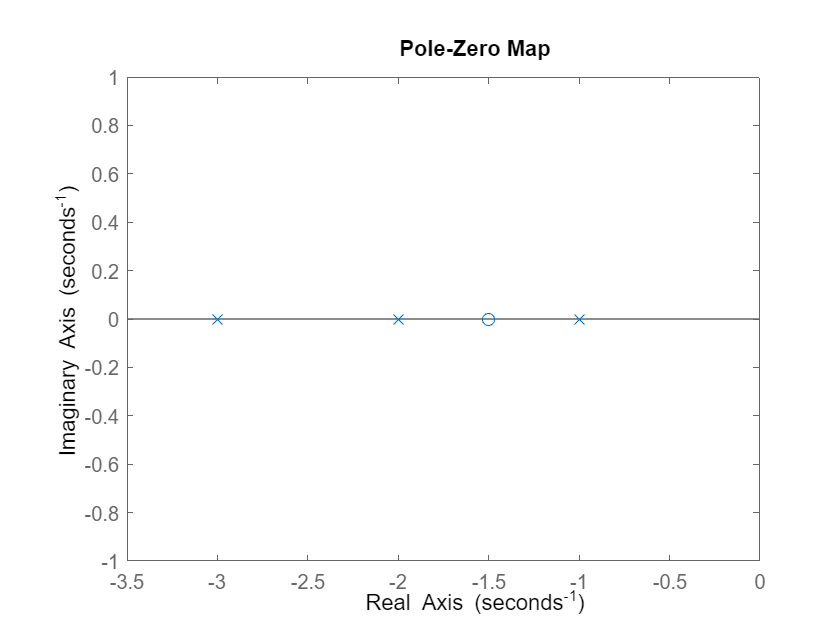

pzmap(ORSys)